# Znajdowanie parametrów teczówki 

# - własna metoda Canny

Zuzanna Rudnicka

249533

Antoni Bezdzietny

249327

Przygotowanie ścieżki do zdjęcia.

image_folder = "database/image_cz/";
eye         = "001" ;
eye_side    = "L_";
eye_variant = "1.png";
image_path = strcat(image_folder,eye,eye_side,eye_variant);

Wczytanie zdjęcia.

img_raw    = imread(image_path); 
img_rgb    = imresize(img_raw, size(img_raw,1:2)*0.5);
img_gray   = rgb2gray(img_rgb);

Wyświetlenie przetwarzanych obrazów w rgb i odcieniach szarości.

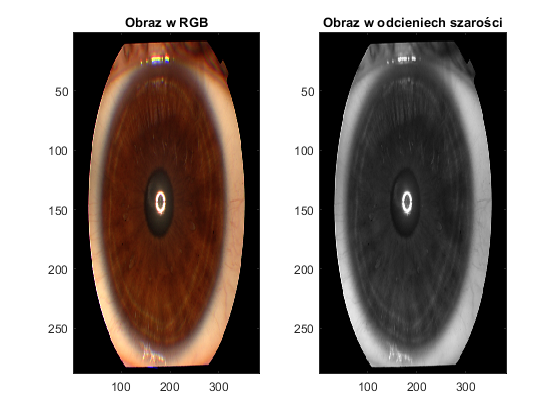

figure(1);
subplot(1,2,1);
image(img_rgb);
title("Obraz w RGB")
subplot(1,2,2)
image(img_gray)
title("Obraz w odcieniech szarości")
colormap("gray");

Detekcja krawędzi metoda Canny.

canny_tresh_low  = 0.008;
canny_tresh_high = 0.045;
canny_sigma      = 1.4142;

`Własna wersja detekcji krawędzi metoda Canny`

- `Rozmycie Gaussa`

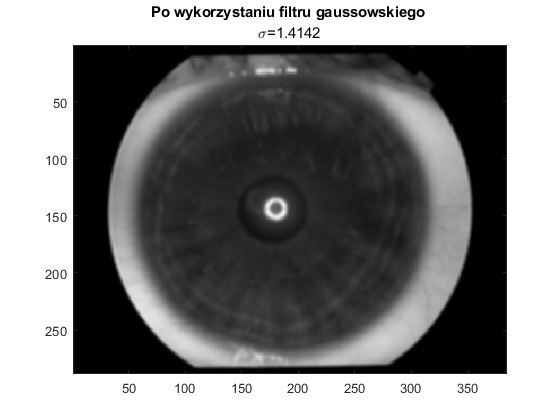

figure(2);
subplot(1,1,1);
addpath("scripts/canny_method");
img_gaussian_blur = gaussianBlur(img_gray,canny_sigma);
image(img_gaussian_blur);
title("Po wykorzystaniu filtru gaussowskiego ","\sigma="+num2str(canny_sigma))

- Gradient

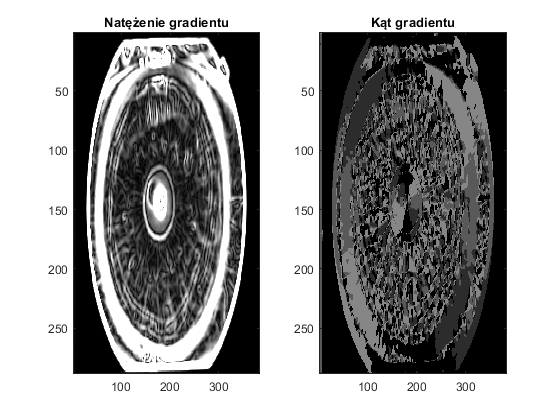

figure(3);
[magnitude,theta] = gradientCanny(img_gaussian_blur);
subplot(1,2,1);
image(magnitude);
title("Natężenie gradientu")
subplot(1,2,2)
image(theta)
title("Kąt gradientu")
colormap("gray");

- Usuwanie wartości niemaksymalnych

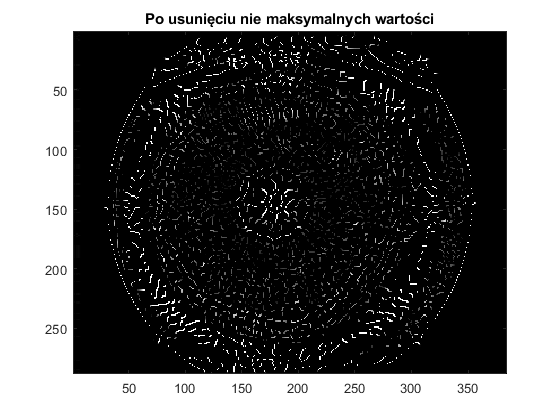

figure(4);
non_maximal = nonMaximalValue(magnitude,theta);
image(non_maximal)
colormap("gray");
title("Po usunięciu nie maksymalnych wartości")

- Progowanie

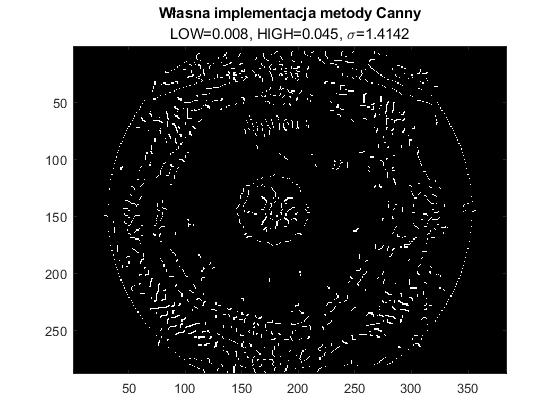

figure(5);
own_canny = thresholding(non_maximal, canny_tresh_low, canny_tresh_high);
imagesc(own_canny)
colormap("gray");
title("Własna implementacja metody Canny", ...
    "LOW="+num2str(canny_tresh_low)+", HIGH="+num2str(canny_tresh_high)+", \sigma="+num2str(canny_sigma))